# 13주차 — 상태궤환 극배치: 극점을 원하는 자리에 정확히

**제어시스템설계** · 충남대학교 자율운항시스템공학과

**참고자료 — 먼저 볼 것**

아래 다섯 과목은 **이 강의의 담당교수가 직접 한 강의**입니다. 기초부터 대학원 과정까지 이어지므로 부족한 곳부터 보면 됩니다. 이 강의에서 쓰는 기호와 유도는 모두 그 안에서 자세히 다룹니다.

**MATLAB 이나 Simulink 가 아직 익숙하지 않다면** 실습에 들어가기 전에 아래를 먼저 하십시오. 무료이고 각각 몇 시간이면 끝납니다.

6~7주차에서 우리는 **정해진 길** 위에서만 극점을 움직일 수 있었습니다. 근궤적이 사양 영역을 비껴가면 방법이 없었고, 그래서 7주차에서 극이나 영을 추가해 **길 자체를 바꿨습니다.**

오늘은 더 나갑니다. **길이라는 것 자체가 없어집니다.** 상태를 전부 되먹이면 극점 $n$ 개를 각각 원하는 자리에 정확히 놓을 수 있습니다.

그리고 학기의 하이라이트 — **거꾸로 선 진자를 실제로 세웁니다.**

if isempty(which('plant_msd'))   % 경로가 아직 등록 안 되었으면 알아서 잡는다
    p_ = pwd;
    if ~isempty(mfilename('fullpath')), p_ = fileparts(mfilename('fullpath')); end
    for k_ = 1:4
        if isfile(fullfile(p_,'setup_path.m')), run(fullfile(p_,'setup_path.m')); break; end
        p_ = fileparts(p_);
    end
    clear p_ k_
end
clc; close all;
s = tf('s');

## 0-0. 오늘 돌려 볼 파일

강의노트를 읽다가 **직접 값을 바꿔 보고 싶을 때** 여는 파일들입니다. 모두 `W13_PolePlacement` 폴더 안에 있습니다.

오늘 처음 쓰는 도우미 함수도 하나 있습니다.

실행하는 법 — 파일을 열고 절 안에서 `Ctrl+Enter` 를 누르면 그 절만 돕니다. 전체는 `F5` 입니다. 처음 한 번은 `setup_path` 를 먼저 실행하십시오.

이 강의노트의 **그림은 전부** `make_figures.m` 이 만들어 `common/figures/` 에 넣어 둔 것입니다. 그림마다 어느 함수가 만들었는지 아래에 적어 두었습니다.

## 0. 오늘 한 장 요약

오늘 배우는 것을 한 문장으로 적으면 이렇습니다.

**상태를 전부 되먹이면 **$A$** 가 **$A - BK$** 로 바뀌고, 가제어이기만 하면 그 고유값을 원하는 자리에 정확히 놓을 수 있다.**

오늘의 계단

- **1~3절** 상태궤환이란 무엇인가. $K$ 를 어떻게 구하는가

- **4~5절** 근궤적과 무엇이 다른가. 그리고 대가는 무엇인가

- **6~8절** 극배치만으로는 부족하다 — $K_r$ 과 적분 상태

- **9~11절** 거꾸로 선 진자를 세운다. **학기의 하이라이트**

- **12절** 포화가 있으면 어떻게 되는가

오늘 딱 하나만 기억한다면 이것입니다.

- **극을 왼쪽으로 보내는 것은 공짜가 아니다.** 제어입력이 폭증한다

## 0-1. 가장 작은 예부터 — 극점 하나 옮기기

이해를 돕기 위해 상태가 **하나뿐인** 시스템부터 봅니다.


$$\dot{x} = 2x + u$$


$a = +2$ 라 그대로 두면 발산합니다. 여기에 $u = -kx$ 를 넣으면


$$\dot{x} = 2x - kx = (2-k)\,x$$


$k = 5$ 로 두면 $\dot{x} = -3x$ 가 되어 **안정해집니다.**

이것이 오늘의 전부입니다. 상태가 여러 개면 $k$ 가 행벡터 $K$ 가 되고 $2-k$ 가 $A - BK$ 가 될 뿐입니다.

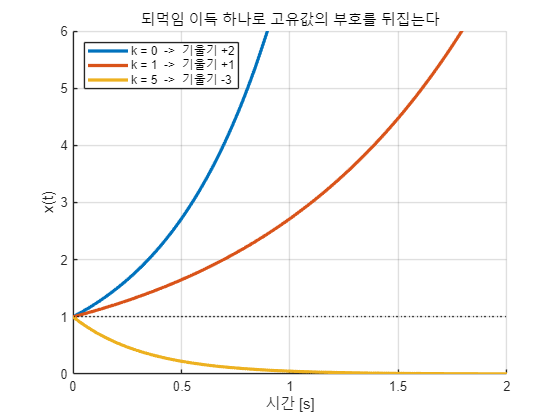

t0 = (0:0.01:2)';
hold on; grid on;
for k = [0 1 5]
    plot(t0, exp((2-k)*t0), 'LineWidth', 2.4, ...
         'DisplayName', sprintf('k = %d  ->  기울기 %+d', k, 2-k));
end
yline(1, 'k:', 'HandleVisibility','off');
xlabel('시간 [s]'); ylabel('x(t)'); ylim([0 6]);
legend('Location','northwest');
title('되먹임 이득 하나로 고유값의 부호를 뒤집는다');

## 1. 상태궤환 — 출력이 아니라 상태를 되먹인다

지금까지 열두 주 동안 되먹인 것은 **출력 **$y$** 하나**였습니다.


$$u = C(s)\,(r - y)$$


상태궤환은 **상태 전부**를 되먹입니다.


$$u = -Kx + K_r r, \qquad K = [k_1\;\;k_2\;\;\cdots\;\;k_n]$$


이것을 상태방정식에 넣으면


$$\dot{x} = Ax + B(-Kx + K_r r) = (A - BK)\,x + BK_r\,r$$


즉 $A$** 가 **$A - BK$** 로 바뀝니다.** 우리가 $K$ 를 고르면 그 고유값을 정할 수 있다는 뜻입니다.

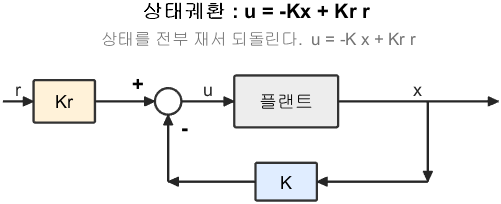

상태궤환 : u = -Kx + Kr r

**그림 파일** `loop_statefb.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_statefb')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('statefeedback', ...)` 로 부릅니다 **직접 확인해 보려면** — `W13_04_run_simulink.m` 이 `W13_PolePlacement.slx` 에서 이 그림 그대로의 블록 배치를 돌립니다

그림 해석

마지막 줄이 오늘 내내 깔려 있는 가정입니다. **이 가정을 깨는 것이 14주차입니다.**

## 2. $K$ 를 손으로 구하기 — 계수비교법

절차는 세 줄입니다.

- **1단계** 원하는 극점으로 원하는 특성다항식을 만든다


$$(s+8)(s+10)(s+12) = s^3 + 30 s^2 + 296 s + 960$$


- **2단계** $A - BK$ 의 특성다항식을 $K$ 의 원소로 적는다

- **3단계** 두 다항식의 **계수를 하나씩 맞춘다**

미지수 개수($K$ 의 원소 $n$ 개)와 방정식 개수(계수 $n$ 개)가 같으므로 **답이 정확히 하나** 나옵니다. 이것이 극배치가 되는 이유입니다.

그리고 12주차의 조건이 여기서 나옵니다 — **가제어여야 합니다.** 가제어가 아니면 위 연립방정식이 풀리지 않습니다.

[Gp, p] = plant_dcmotor('position');
sys = ss(p.A, p.B, p.C, p.D);
p_des = [-8 -10 -12];
K = place(p.A, p.B, p_des);
fprintf('개루프 고유값 : %s\n', mat2str(round(eig(p.A).', 4)));

개루프 고유값 : [0 -9.9975 -2.0025]


fprintf('원하는 특성다항식 계수 : %s\n', mat2str(round(poly(p_des), 4)));

원하는 특성다항식 계수 : [1 30 296 960]


fprintf('place 로 구한 K = %s\n', mat2str(round(K, 4)));

place 로 구한 K = [480 47.99 9]


fprintf('검증 eig(A-BK) = %s\n', mat2str(round(sort(eig(p.A-p.B*K)).', 4)));

검증 eig(A-BK) = [-12 -10 -8]


## 2-1. 계수비교를 **직접** 해 본다 — 가장 작은 예

위에서는 절차만 말하고 `place` 에 맡겼습니다. 그러면 무슨 일이 일어나는지 안 보이므로, 상태가 둘뿐인 예로 손으로 풉니다.


$$A = \left[\begin{array}{cc} 0 & 1 \\ -2 & -3 \end{array}\right], \qquad B = \left[\begin{array}{c} 0 \\ 1 \end{array}\right], \qquad K = \left[\begin{array}{cc} k_1 & k_2 \end{array}\right]$$


**1단계** — 원하는 극점을 $-4$, $-5$ 로 두면


$$(s+4)(s+5) = s^2 + 9s + 20$$


**2단계** — $A - BK$ 를 만들고 특성다항식을 $k_1, k_2$ 로 적습니다.


$$A - BK = \left[\begin{array}{cc} 0 & 1 \\ -2-k_1 & -3-k_2 \end{array}\right]$$


$2\times2$ 행렬의 특성다항식은 $s^2 - (\text{대각합})s + (\text{행렬식})$ 이므로


$$s^2 + (3+k_2)\,s + (2+k_1)$$


**3단계** — 두 다항식의 계수를 하나씩 맞춥니다.

따라서 $K = \left[\begin{array}{cc} 18 & 6 \end{array}\right]$ 입니다. **미지수 두 개, 방정식 두 개.** 그래서 답이 딱 하나 나옵니다.

지금 한 일을 한 장으로 묶으면 이렇습니다.

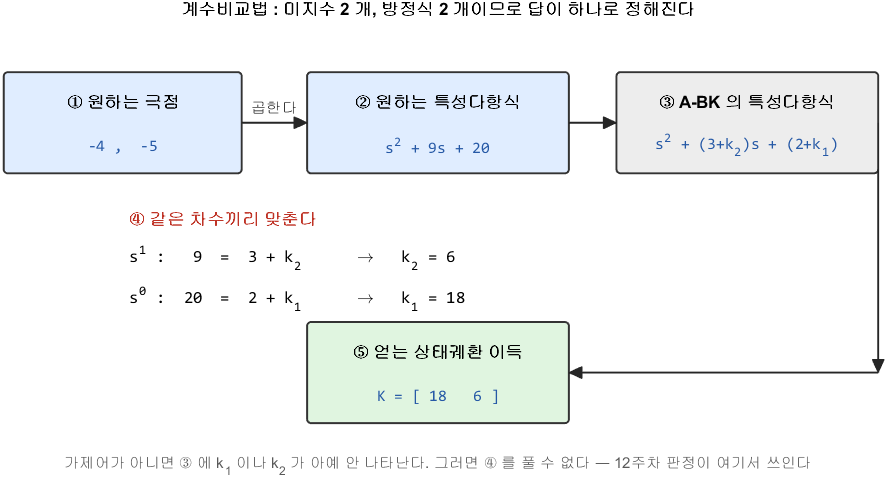

계수비교법 — 원하는 극점에서 K 까지

**그림 파일** `w13_coeff_match.png` — `make_figures.m` 의 `fig_w13_coeff_match` · 다시 만들려면 `make_figures('w13_coeff_match')`

**만드는 곳** — `make_figures.m` 의 `fig_w13_coeff_match` **직접 확인해 보려면** — `W13_01_pole_placement.m` 의 **2절**이 같은 예제를 손계산과 `place` 로 나란히 풉니다

그림 해석

③ 에 $k_1$ 이나 $k_2$ 가 **아예 나타나지 않는 경우**가 있습니다. 그러면 ④ 를 풀 수 없습니다. 그것이 **가제어가 아닌 경우**입니다. 12주차의 판정이 여기서 쓰입니다.

A2 = [0 1; -2 -3];  B2 = [0; 1];
K2_hand  = [18 6];
K2_place = place(A2, B2, [-4 -5]);
fprintf('\n=== 계수비교법 손계산 확인 ===\n');


=== 계수비교법 손계산 확인 ===


fprintf('  손으로 푼 K   : %s\n', mat2str(K2_hand));

  손으로 푼 K   : [18 6]


fprintf('  place 가 준 K : %s\n', mat2str(round(K2_place, 4)));

  place 가 준 K : [18 6]


fprintf('  A-BK 특성다항식 : %s   (원하는 것 : %s)\n', ...
        mat2str(round(poly(A2 - B2*K2_hand), 4)), mat2str(poly([-4 -5])));

  A-BK 특성다항식 : [1 9 20]   (원하는 것 : [1 9 20])


fprintf('  eig(A-BK) = %s\n', mat2str(round(sort(eig(A2 - B2*K2_hand)).', 4)));

  eig(A-BK) = [-5 -4]


## 2-2. 3차에서는 기호 계산으로 맡긴다

상태가 셋이 되면 손으로 전개하기가 번거롭습니다. 그래도 **원리는 똑같다**는 것을 확인하기 위해 기호로 풀어 봅니다.

Symbolic Math Toolbox 의 `charpoly` 가 특성다항식을 $k_1,k_2,k_3$ 이 들어간 채로 만들어 주고, `solve` 가 계수를 맞춰 줍니다.

새로 나오는 명령 두 개

- `charpoly(M, s)` — 행렬 `M` 의 특성다항식을 변수 `s` 로 돌려준다

- `coeffs(expr, s, 'All')` — 다항식의 계수를 **높은 차수부터 전부** 뽑는다

우리 DC 모터의 $A - BK$ 특성다항식은 이렇게 나옵니다.


$$s^3 + (2k_3 + 12)\,s^2 + \left(2k_2 + 20k_3 + \frac{1001}{50}\right)s + 2k_1$$


원하는 다항식 $s^3 + 30s^2 + 296s + 960$ 과 계수를 맞추면 미지수 세 개에 방정식 세 개이므로 답이 하나로 정해집니다. [주의] 이 절만 Symbolic Math Toolbox 가 필요합니다. 없는 PC 에서도 강의노트가 끝까지 돌도록 확인하고 건너뜁니다.

hasSym = license('test','Symbolic_Toolbox') && ~isempty(which('syms'));

if hasSym
    syms k1 k2 k3 sv real
    Ksym = [k1 k2 k3];
    cpoly = expand(charpoly(sym(p.A) - sym(p.B)*Ksym, sv));
    wpoly = expand(poly2sym(poly(p_des), sv));
    sol   = solve(coeffs(cpoly - wpoly, sv, 'All') == 0, [k1 k2 k3]);
    K_hand3 = double([sol.k1 sol.k2 sol.k3]);

    fprintf('\n=== 3차도 같은 방법으로 ===\n');
    fprintf('  계수비교로 푼 K : %s\n', mat2str(round(K_hand3, 4)));
    fprintf('  place 가 준 K   : %s\n', mat2str(round(K, 4)));
    fprintf('  두 결과의 차이   : %.2e\n', max(abs(K_hand3 - K)));
else
    fprintf('\n=== 3차도 같은 방법으로 ===\n');
    fprintf('  Symbolic Math Toolbox 가 없어 기호 계산은 건너뜁니다.\n');
    fprintf('  계수만 대조해도 같은 확인이 됩니다.\n');
    fprintf('  원하는 특성다항식 : %s\n', mat2str(round(poly(p_des), 4)));
    fprintf('  A-BK 의 특성다항식 : %s\n', mat2str(round(poly(p.A - p.B*K), 4)));
end


=== 3차도 같은 방법으로 ===


  계수비교로 푼 K : [480 47.99 9]


  place 가 준 K   : [480 47.99 9]


  두 결과의 차이   : 1.93e-12


fprintf('  --> `place` 는 이 연립방정식을 수치적으로 푸는 명령일 뿐입니다.\n');

  --> `place` 는 이 연립방정식을 수치적으로 푸는 명령일 뿐입니다.


## 3. `place` 와 `acker` — 오늘의 새 명령 둘

둘 다 같은 일을 합니다. 그런데 쓰는 자리가 다릅니다.

주의 세 가지

- 둘 다 **개루프** $A, B$ 를 받습니다. 폐루프를 넣으면 안 됩니다

- 돌려주는 것은 $K$ 이고, 실제 제어입력은 $u = -Kx$ 입니다. **부호에 주의**

- `place` 가 오류를 내면 두 가지 중 하나입니다 — **중근을 줬거나, 가제어가 아니거나**

예제 — 중근을 주면 어떻게 되는지 확인해 봅니다.

try
    K2 = place(p.A, p.B, [-10 -10 -10]);
catch ME
    fprintf('place([-10 -10 -10]) : 오류!\n  %s\n\n', ME.message);
end

place([-10 -10 -10]) : 오류!
  "place" 명령은 rank(B)보다 큰 중복도를 갖는 극점을 배치할 수 없습니다.



K2 = acker(p.A, p.B, [-10 -10 -10]);
fprintf('acker([-10 -10 -10]) : K = %s\n', mat2str(round(K2, 3)));

acker([-10 -10 -10]) : K = [500 49.99 9]


fprintf('  검증 eig = %s\n', mat2str(round(sort(eig(p.A-p.B*K2)).', 3)));

  검증 eig = [-10 -10 -10]


## 4. 근궤적과 무엇이 다른가 — 오늘의 핵심

6~7주차에서는 이득 $K$ **하나**를 바꿨습니다. 자유도가 하나뿐이라 극점이 **정해진 길** 위를 움직였습니다.

상태궤환은 $K$ 가 **벡터**입니다. 자유도가 상태 개수만큼 있습니다. 그래서 극점 $n$ 개를 각각 원하는 자리에 놓을 수 있습니다.

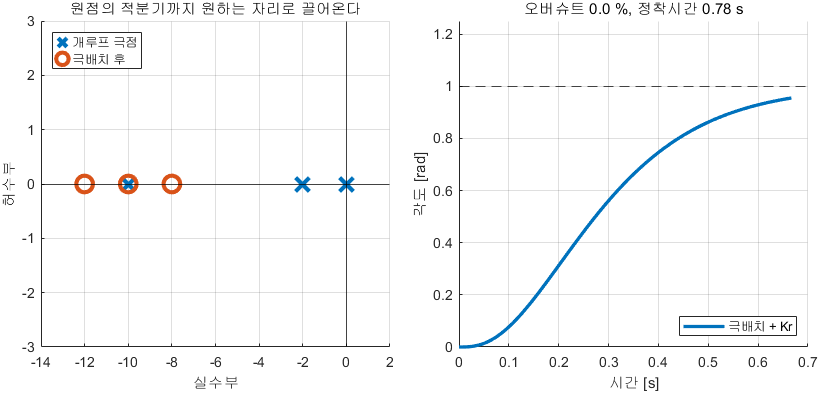

원점의 적분기까지 원하는 자리로 끌어온다

**그림 파일** `w13_place_map.png` — `make_figures.m` 의 `fig_place_map` · 다시 만들려면 `make_figures('w13_place_map')`

**만드는 곳** — `make_figures.m` 의 `fig_place_map` **직접 바꿔 보려면** — `W13_01_pole_placement.m` 의 **4절**이 근궤적을 배경으로 깔고 극배치 결과를 겹쳐 그립니다

그림 해석

**원점 극점을 옮겼다**는 것이 이 그림의 핵심입니다. 비례제어에서는 원점 극점이 그 자리에서 출발해 오른쪽으로 휘어 갈 뿐이었습니다.

## 5. 대가 — 극을 왼쪽으로 보낼수록

수학적으로는 **어디든** 놓을 수 있습니다. 가제어이기만 하면요. 그런데 물리적으로는 대가가 있습니다.

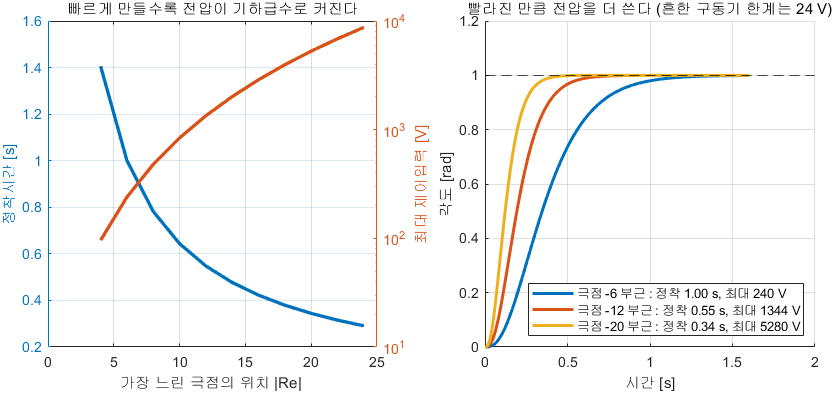

빨라진 만큼 전압을 더 쓴다

**그림 파일** `w13_effort.png` — `make_figures.m` 의 `fig_effort` · 다시 만들려면 `make_figures('w13_effort')`

**만드는 곳** — `make_figures.m` 의 `fig_effort` **직접 바꿔 보려면** — `W13_01_pole_placement.m` 의 **5절**에서 `a_list` 를 바꿔 실행

그림 해석 — **왼쪽 두 곡선의 세로축 눈금을 반드시 함께 보십시오**

이 그림이 오늘의 실무적 결론입니다. **"가장 빠른 설계" 가 아니라 "구동기가 낼 수 있는 것 중 가장 좋은 설계"** 를 골라야 합니다. 6주차의 포화, 7주차의 Lead 대가와 똑같은 이야기입니다.

## 6. 극배치만으로는 부족하다 — 어디에 멈출 것인가

극배치는 $A$ 를 $A - BK$ 로 바꿔 **고유값만** 옮깁니다. 직류이득은 아무도 신경 쓰지 않았습니다.

그래서 지령 $r$ 을 그대로 넣으면 엉뚱한 값에 수렴합니다.

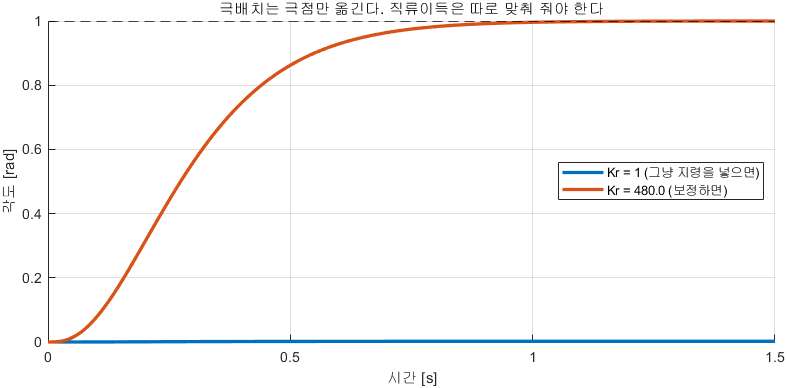

극배치는 극점만 옮긴다. 직류이득은 따로 맞춰야 한다

**그림 파일** `w13_kr.png` — `make_figures.m` 의 `fig_kr` · 다시 만들려면 `make_figures('w13_kr')`

**만드는 곳** — `make_figures.m` 의 `fig_kr` **직접 확인해 보려면** — `W13_02_reference_tracking.m` 의 **1~2절**

그림 해석

**모양은 같고 크기만 다르다** — 이것을 놓치지 마십시오. $K_r$ 은 과도응답을 전혀 안 바꿉니다.

## 7. $K_r$ 은 어떻게 구하는가

정상상태에서는 $\dot{x} = 0$ 이므로


$$0 = (A - BK)\,x_{ss} + BK_r\,r \qquad\Rightarrow\qquad x_{ss} = -(A-BK)^{-1}BK_r\,r$$



$$y_{ss} = C\,x_{ss} = -C(A-BK)^{-1}B\,K_r\,r$$


이것이 $r$ 과 같아지려면


$$K_r = \frac{1}{-C(A-BK)^{-1}B} = \frac{1}{\mathrm{dcgain}(A-BK,\,B,\,C,\,D)}$$


MATLAB 에서는 한 줄입니다.

Kr = 1/dcgain(ss(p.A - p.B*K, p.B, p.C, p.D));
fprintf('Kr = %.2f\n', Kr);

Kr = 480.00


fprintf('보정 후 직류이득 = %.6f\n', ...
        dcgain(ss(p.A - p.B*K, p.B*Kr, p.C, p.D)));

보정 후 직류이득 = 1.000000


## 8. $K_r$ 의 약점과 적분 상태

$K_r$ 은 **모델을 믿고 미리 계산한 값**입니다. 1주차와 5주차에서 본 그 문제가 그대로 돌아옵니다.

그런데 **한 가지 예외가 있습니다.**

- 플랜트 안에 **적분기가 이미 있으면** ($A$ 의 첫 열이 $0$) $K_r$ 만으로도 계단 오차가 저절로 $0$ 이 됩니다

- 없으면 $K_r$ 은 모델 오차만큼 그대로 어긋납니다

오늘 쓰는 DC 모터 **위치** 모델은 앞쪽입니다 (각도는 각속도의 적분). **속도** 모델은 뒤쪽입니다. `W13_02_reference_tracking.m` 의 3절에서 두 경우를 나란히 확인합니다.

확실히 없애려면 **적분 상태를 하나 더** 넣습니다.


$$\dot{x}_i = r - y$$



$$\left[\begin{array}{c}\dot{x}\\ \dot{x}_i\end{array}\right] = \left[\begin{array}{cc}A & 0\\ -C & 0\end{array}\right] \left[\begin{array}{c}x\\ x_i\end{array}\right] + \left[\begin{array}{c}B\\ 0\end{array}\right] u + \left[\begin{array}{c}0\\ 1\end{array}\right] r$$


이 확대 시스템에 극배치를 하면 상태가 $n+1$ 개인 제어기가 나옵니다. **서보 문제**라고 부르며, 모델이 틀려도 정상상태 오차가 $0$ 입니다.

두 방식의 차이는 **모델이 틀렸을 때** 드러납니다.

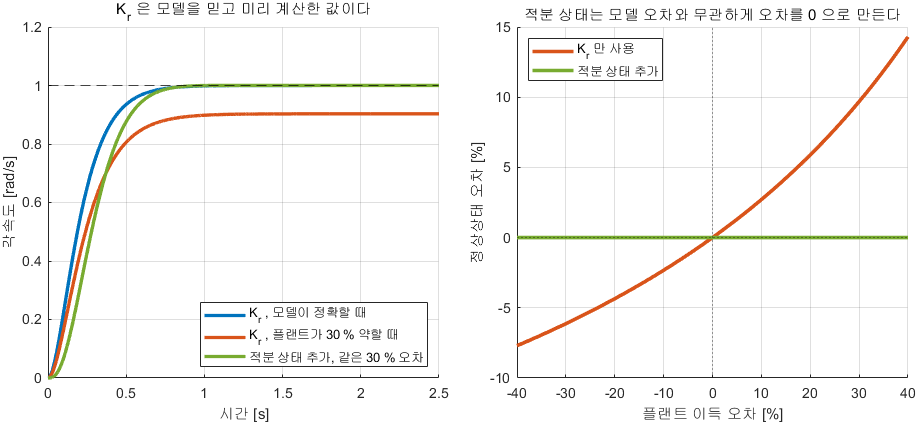

K_r 만 쓸 때와 적분 상태를 더했을 때

**그림 파일** `w13_servo.png` — `make_figures.m` 의 `fig_w13_servo` · 다시 만들려면 `make_figures('w13_servo')`

**만드는 곳** — `make_figures.m` 의 `fig_w13_servo` **직접 바꿔 보려면** — `W13_02_reference_tracking.m` 의 **3-1절**과 **4절** 에서 모델 오차의 크기를 바꿔 보십시오

그림 해석

오른쪽 그림이 이 절의 결론입니다. $K_r$ 은 **모델을 믿는** 앞먹임이고, 적분 상태는 **출력을 보는** 되먹임입니다. 1주차에서 개루프와 폐루프를 비교하며 한 이야기가 그대로 돌아왔습니다.

상태궤환에 적분 상태를 더한 것이 **사실상 PID** 입니다.

- 각도에 비례해서 미는 것 — $P$

- 각속도에 비례해서 빼는 것 — $D$ (각속도는 각도의 미분)

- 적분 상태 — $I$

**다만 미분을 안 합니다.** 이미 있는 상태를 쓸 뿐입니다. 7주차에서 고생한 미분 잡음 증폭이 여기서는 안 생깁니다.

## 9. 학기의 하이라이트 — 거꾸로 선 진자

3주차에서 이 진자를 처음 만났습니다. 거꾸로 세우면 고유값 하나가 $+5.72$ 가 되어 **손을 떼면 넘어간다**는 것을 봤습니다.

12주차에서 가제어임을 확인했습니다. 그러니 세울 수 있습니다. 오늘 실제로 세웁니다.

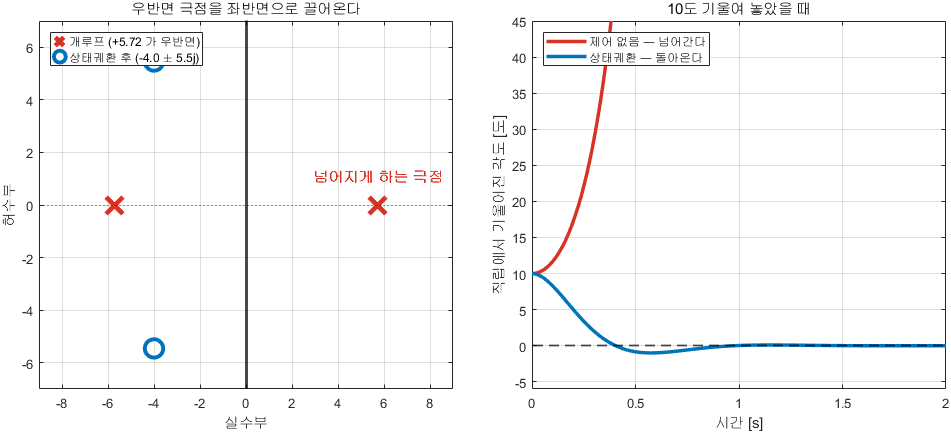

우반면 극점을 좌반면으로 끌어온다

**그림 파일** `w13_pendulum.png` — `make_figures.m` 의 `fig_w13_pendulum` · 다시 만들려면 `make_figures('w13_pendulum')`

**만드는 곳** — `make_figures.m` 의 `fig_w13_pendulum` **직접 해 보려면** — `W13_03_pendulum_balance.m` 의 **2절**

그림 해석

$+5.72$ 라는 숫자를 다시 보십시오. 시정수가 $0.175$ 초입니다. $175$** ms 마다 기울기가 **$e$** 배씩 커집니다.** 사람 반응속도로는 못 잡습니다.

## 10. 선형 설계가 진짜 진자에서도 통하는가

우리가 설계한 $K$ 는 **선형 모델**을 보고 만든 것입니다. 진짜 진자는 비선형입니다 ($\sin$ 이 들어 있습니다).

3주차의 마지막 교훈이 여기서 적용됩니다 — **설계한 제어기를 다시 비선형 모델에 붙여서 검증한다.**

`W13_03_pendulum_balance.m` 의 4절이 그 검증입니다.

- $10$ 도에서 놓으면 — 비선형과 선형이 거의 겹친다

- $40$ 도에서 놓으면 — 둘 다 세워지지만 **가는 길이 다르다**

**좌표에 주의하십시오.** 이 실습에서 가장 틀리기 쉬운 부분입니다.

- `plant_pendulum` 의 비선형 함수 `p.f` 는 **매달린 자세 기준 절대 각도**를 받습니다

- 선형 모델 $(A, B)$ 는 **직립 기준 편차**입니다

그래서 비선형 시뮬레이션에 제어기를 붙일 때는 이렇게 씁니다.

- 편차 $\delta x = [\theta - \pi;\;\dot{\theta}]$

- 제어입력 $u = u_0 - K\,\delta x$, 여기서 $u_0 = mgl\sin\pi = 0$

이것을 빼먹으면 "직립에서 $10$ 도" 를 "매달린 데서 $10$ 도" 로 잘못 넣게 되어 **아무 제어기나 다 성공하는 것처럼** 보입니다. 불안정 플랜트인데 뭘 해도 잘되면 좌표를 의심하십시오.

초기각을 키워 가며 선형 예측과 실제를 겹쳐 보면 이렇습니다.

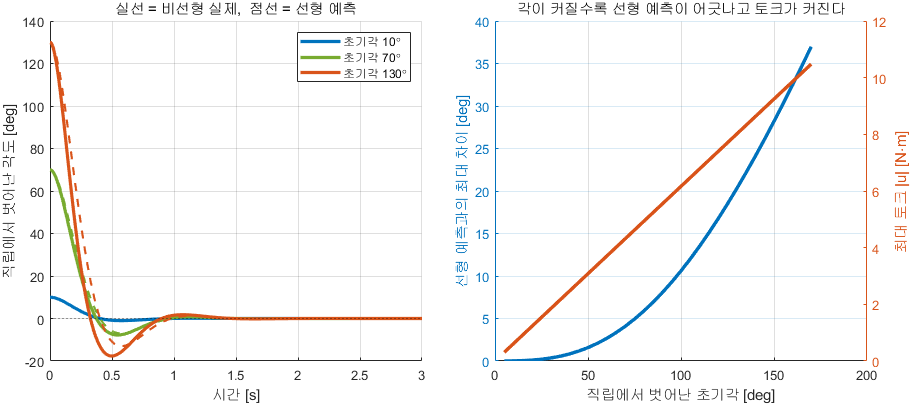

선형 예측과 비선형 실제가 어디서부터 벌어지는가

**그림 파일** `w13_nonlin_check.png` — `make_figures.m` 의 `fig_w13_nonlin_check` · 다시 만들려면 `make_figures('w13_nonlin_check')`

**만드는 곳** — `make_figures.m` 의 `fig_w13_nonlin_check` **직접 바꿔 보려면** — `W13_03_pendulum_balance.m` 의 **4절**에서 초기각을 바꿔 가며 같은 비교를 합니다

그림 해석

여기서 나오는 결론이 중요합니다. **선형 설계가 실패하는 이유는 각도가 커서가 아니라 토크가 모자라서**입니다. 위 그림은 토크를 무한히 낼 수 있다고 가정한 것입니다. 진짜 한계는 다음 절에서 봅니다.

## 11. 진짜 한계는 토크다

10절에서 $40$ 도까지도 세워졌습니다. 그런데 그건 **토크를 무한히 낼 수 있다고 가정**했기 때문입니다.

실제 모터는 정해진 토크까지만 냅니다.

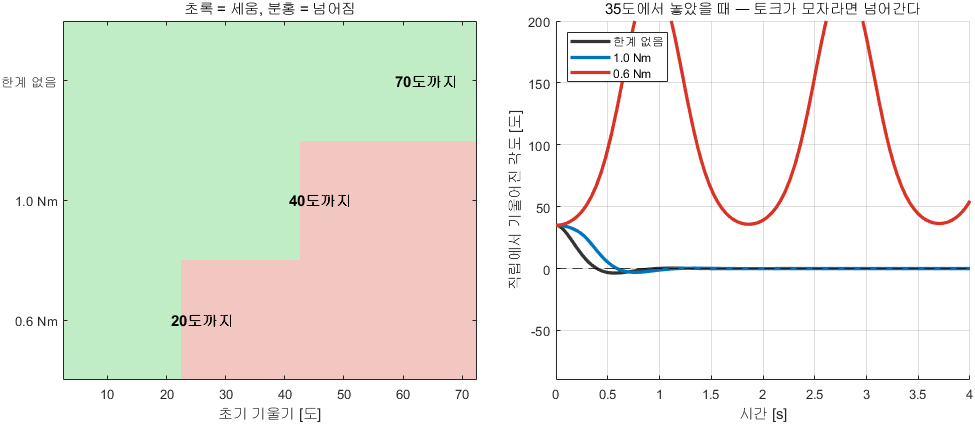

토크가 모자라면 넘어간다

**그림 파일** `w13_saturation.png` — `make_figures.m` 의 `fig_w13_saturation` · 다시 만들려면 `make_figures('w13_saturation')`

**만드는 곳** — `make_figures.m` 의 `fig_w13_saturation` **직접 바꿔 보려면** — `W13_03_pendulum_balance.m` 의 **5절**에서 `tau_lim` 목록을 바꿔 실행

그림 해석

여기서 배울 것 — **유효범위를 정하는 것은 선형화가 아니라 토크입니다.** 3주차에서는 "선형화가 몇 도까지 맞는가" 를 물었지만, 실제 한계는 그보다 훨씬 앞에서 **구동기가 정합니다.**

10강 slide 106~108 의 control saturation 이 정확히 이 이야기입니다.

## 12. Simulink 로 확인 — 포화가 있는 루프

모델 `W13_PolePlacement.slx` 를 열어 보십시오. 지금까지의 모델과 딱 두 가지가 다릅니다.

- 되먹임 경로의 `Gain` 블록에 **스칼라가 아니라 행벡터 **$K$ 가 들어 있다 (Multiplication 을 `Matrix(K*u)` 로 두어야 합니다)

- 플랜트의 $C$ 가 **단위행렬**이다 (상태를 전부 뽑는다)

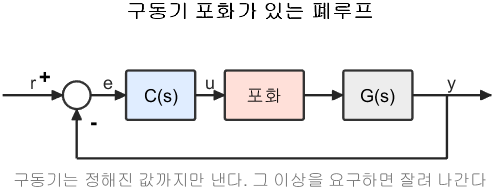

구동기 포화가 있는 폐루프

**그림 파일** `loop_saturation.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_saturation')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('saturation', ...)` 로 부릅니다

그림 해석

`W13_04_run_simulink.m` 을 실행하면 다음을 확인합니다.

제어입력 그림에서 **평평하게 잘린 구간**이 포화된 시간입니다. 그 시간 동안 제어기는 "더 주라" 고 하는데 구동기가 못 냅니다.

11주차의 와인드업은 여기에 **적분기까지 있을 때** 생기는 한 걸음 더 나간 문제입니다.

## 12-1. `place` 와 `acker` 를 여러 가지로 써 본다

두 명령은 같은 문제를 풀지만 **쓸 수 있는 자리가 다릅니다.**

중근을 `place` 에 주면 다음과 같은 오류가 납니다.

- `"place" 명령은 rank(B) 보다 큰 중복도를 갖는 극점을 배치할 수 없습니다`

단입력이면 `rank(B) = 1` 이므로 **같은 극을 두 번 쓸 수 없다**는 뜻입니다. 실무에서는 중근을 굳이 쓸 이유가 거의 없으므로 $-10$ 대신 $-10.0$ 과 $-10.1$ 처럼 아주 조금 떨어뜨려 주면 됩니다.

[~, pB] = plant_dcmotor('position');
Ap = pB.A;  Bp = pB.B;
p_want = [-8 -10 -12];

K_place = place(Ap, Bp, p_want);
K_acker = acker(Ap, Bp, p_want);
fprintf('place : %s\n', mat2str(round(K_place, 4)));

place : [480 47.99 9]


fprintf('acker : %s\n', mat2str(round(K_acker, 4)));

acker : [480 47.99 9]


fprintf('두 결과의 최대 차이 : %.2e  (같습니다)\n', max(abs(K_place - K_acker)));

두 결과의 최대 차이 : 1.93e-12  (같습니다)



% 정말 원하는 자리에 갔는지 반드시 확인한다
fprintf('\n원한 극점 : %s\n', mat2str(p_want));


원한 극점 : [-8 -10 -12]


fprintf('실제 극점 : %s\n', mat2str(round(sort(eig(Ap - Bp*K_place)).', 4)));

실제 극점 : [-12 -10 -8]



% 중근을 요구하면 place 는 거부한다
try
    place(Ap, Bp, [-10 -10 -12]);
catch ME
    fprintf('\nplace 에 중근을 주면 : %s\n', ME.message);
end


place 에 중근을 주면 : "place" 명령은 rank(B)보다 큰 중복도를 갖는 극점을 배치할 수 없습니다.


K_rep = acker(Ap, Bp, [-10 -10 -12]);
fprintf('acker 로는 됩니다 : %s\n', mat2str(round(K_rep, 4)));

acker 로는 됩니다 : [600 59.99 10]


fprintf('대신 이득이 %.0f %% 커졌습니다. 극을 왼쪽으로 모은 대가입니다.\n', ...
        100*(K_rep(1)/K_place(1) - 1));

대신 이득이 25 % 커졌습니다. 극을 왼쪽으로 모은 대가입니다.


## 13. 오늘의 정리

- 상태궤환 $u = -Kx$ 는 $A$ 를 $A - BK$ 로 바꾼다

- 가제어이기만 하면 극점 $n$ 개를 **원하는 자리에 정확히** 놓을 수 있다

- $K$ 는 계수비교법으로 손계산할 수 있고, `place` / `acker` 가 대신 해 준다

- `place` 는 중근 불가, `acker` 는 단일입력만. 기본은 **place** 를 쓴다

- 근궤적과 달리 **정해진 길이 없다.** 자유도가 상태 개수만큼 있다

- 극배치는 극점만 옮긴다. **어디에 멈출지는 **$K_r$** 이나 적분 상태가 정한다**

- 상태궤환 $+$ 적분 상태 $=$ 사실상 PID. 다만 **미분을 안 해 잡음이 없다**

- 거꾸로 선 진자의 $+5.72$ 를 좌반면으로 옮겨 **세웠다**

- **극을 왼쪽으로 보내는 것은 공짜가 아니다.** 제어입력이 폭증한다

- 유효범위를 정하는 것은 선형화가 아니라 **구동기 토크**다

## 14. 다음 주 예고

오늘 내내 깔려 있던 가정이 하나 있습니다.

$u = -Kx$** 를 쓰려면 **$x$** 를 전부 알아야 합니다.**

그런데 현실에서는 상태를 전부 잴 수 없습니다.

- 진자에서는 각도만 잰다. 각속도계는 비싸고 잡음이 많다

- DC 모터에서는 각도만 잰다. 전류를 재려면 센서를 더 달아야 한다

14주차에서는 **못 재는 상태를 만들어 냅니다.**

- 같은 모델을 컴퓨터 안에서 함께 돌린다

- 잰 출력과 예상한 출력의 **차이를 보고** 추정을 고친다

- 이것을 **관측기**라고 한다

그리고 놀라운 사실 하나를 배웁니다 — **제어기 설계와 관측기 설계를 따로 해도 된다** (분리원리).

12주차에서 확인한 **가관측성**이 그 입장권입니다. 거꾸로 선 진자는 각도 하나만 재도 가관측이었습니다. 그러니 됩니다.